#### Задача 3.4.

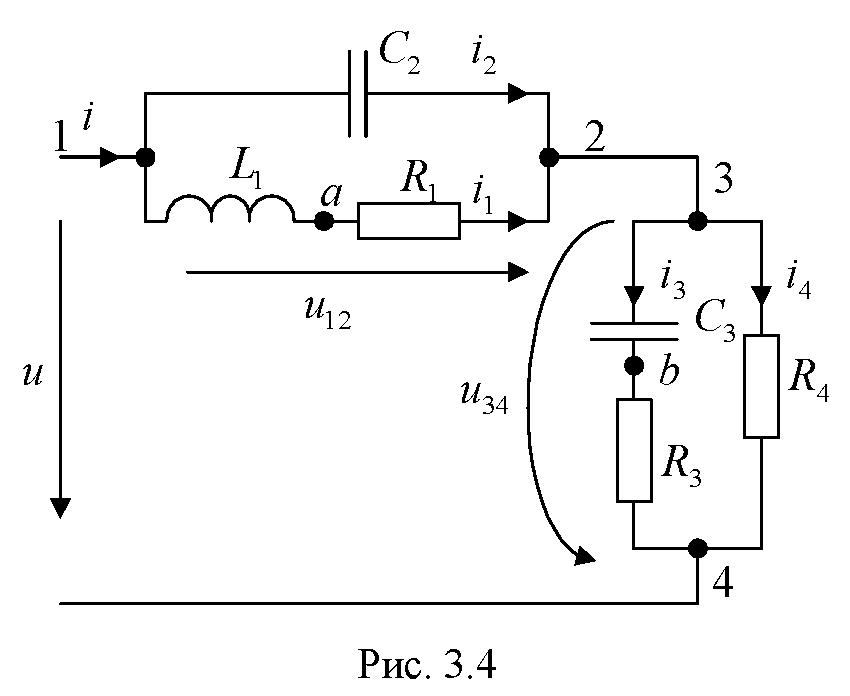

% Рис.3.4
clear
format short
digits(2)
U=220; % В
R1=91; % Ом
R3=510; % Ом
R4=820; % Ом
X1=240; % Ом, =omega*L1
X2=150; % Ом, =1/omega*C2
X3=190; % Ом, = 1/omega*C3

Комплексные сопротивления ветвей

Z1=R1+1j*X1

Z1 = 9.1000e+01 + 2.4000e+02i

Z2=-1j*X2

Z2 = 0.0000e+00 - 1.5000e+02i

Z3=R3-1j*X3

Z3 = 5.1000e+02 - 1.9000e+02i

Z4=R4

Z4 = 820

% Для расчета Рис.3.5

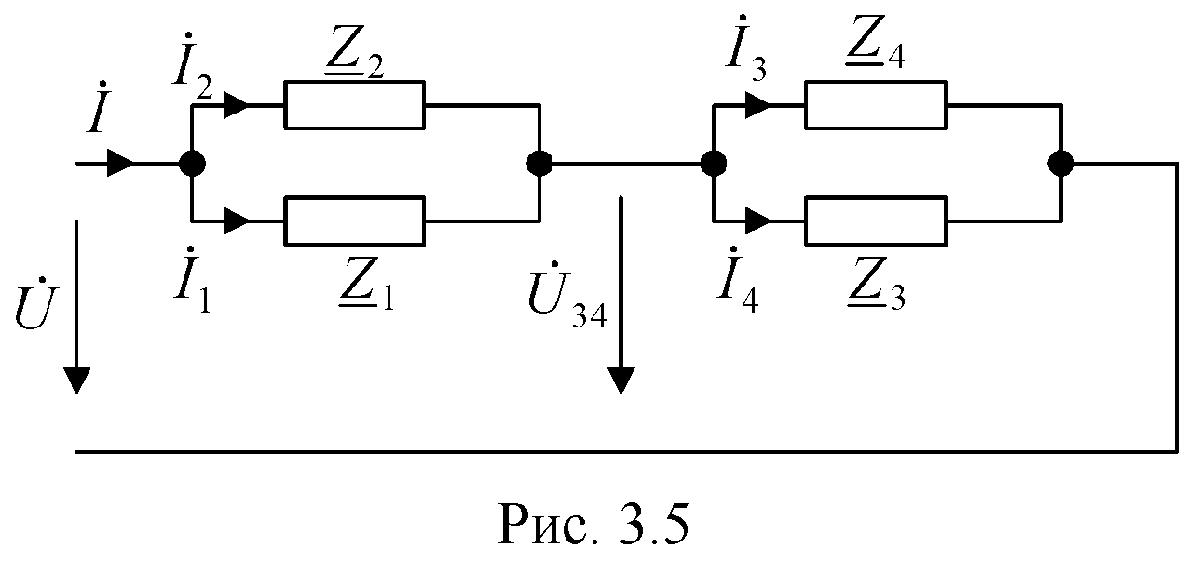

Узловое уравнение

% (1/Z1+1/Z2+1/Z3+1/Z4)*U34-(1/Z1+1/Z2)*U==0
% откуда
U34=vpa(U*(1/Z1+1/Z2)/(1/Z1+1/Z2+1/Z3+1/Z4))

$$U34 = 122.0+55.0\,\mathrm{i}$$

Токи ветвей

I1=(U-U34)/Z1, Ip1=vpa([abs(I1),angle(I1)*180/pi])

$$I1 = -0.057-0.45\,\mathrm{i}$$

$$Ip1 = \left(\begin{array}{cc} 0.46 & -97.0 \end{array}\right)$$

I2=(U-U34)/Z2, Ip2=vpa([abs(I2),angle(I2)*180/pi])

$$I2 = 0.37+0.69\,\mathrm{i}$$

$$Ip2 = \left(\begin{array}{cc} 0.78 & 62.0 \end{array}\right)$$

I3=U34/Z3, Ip3=vpa([abs(I3),angle(I3)*180/pi])

$$I3 = 0.17+0.17\,\mathrm{i}$$

$$Ip3 = \left(\begin{array}{cc} 0.24 & 46.0 \end{array}\right)$$

I4=U34/Z4, Ip4=vpa([abs(I4),angle(I4)*180/pi])

$$I4 = 0.14+0.067\,\mathrm{i}$$

$$Ip4 = \left(\begin{array}{cc} 0.16 & 25.0 \end{array}\right)$$

I=I1+I2, Ip=vpa([abs(I),angle(I)*180/pi])

$$I = 0.31+0.24\,\mathrm{i}$$

$$Ip = \left(\begin{array}{cc} 0.39 & 37.0 \end{array}\right)$$